# RAMPKAR PAPER - R2H, R2P xcorr

## Exploring the xcorr, forced lag data

% Figure 2 - Cross-correlation RAMPKAR2-HYlight and RAMPKAR2-Perceval

% basic paths
addpath('\\albecklab.mcb.ucdavis.edu\data\Code\DatalocHandler\', ...
    '\\albecklab.mcb.ucdavis.edu\data\Code\Image Analysis\', ...
    '\\albecklab.mcb.ucdavis.edu\data\Code\Cell Trace\')

iBasePath = '\\albecklab.mcb.ucdavis.edu\data\imageData\RAMPKAR\';
pBasePath = '\\albecklab.mcb.ucdavis.edu\data\Processed Data\RAMPKAR\';

%% Load the data for RAMPKAR-HYlight for crosscorr

% List of replicate subpaths (relative to pBasePath)
replicatePaths = {
    '2023-09-26 10A RAMPKAR2 HYLIGHT\2023-09-26 10A RAMPKAR2 HYLIGHT_Processed.mat' % has MTK + oligo  treatment
    '2023-09-25 10A RAMPKAR2 HYLIGHT\2023-09-25 10A RAMPKAR2 HYLIGHT_Processed.mat' % has MTK + oligo  treatment
    '2025-06-10_MCF10A_R2HmO_R2P\2025-06-10_MCF10A_R2HmO_R2P_Processed.mat'% has MTK + oligo  treatment
    '2025-05-22_MCF10A_R2HmO_R2P\2025-05-22_MCF10A_R2HmO_R2P_Processed.mat' % this one is behaving very weirdly (vehicle) after Perceval pwrat
    '2025-05-14_MCF10A_R2HmO_R2P\2025-05-14_MCF10A_R2HmO_R2P_Processed.mat'}; 

% Preallocate
f2Data = cell(1, numel(replicatePaths));

% Load in a loop
for i = 1:numel(replicatePaths)
    f2D = load([pBasePath, replicatePaths{i}]);
    f2Data{i} = f2D.dataloc;
end

%% Force a lag of 0 minutes for Hylight
% Markhus' datasets
for i = 1:2
    deltaR2_HY = convertPulseToDataframe(f2Data{i}, {'HYLIGHT','RAMPKAR2'}, ...
        'pulsepars', {'Delta_Mean','Mean_Before'}, ...
        'aftertx', 1, 'tmaxback', 3, ...
        'crosscorr', {'HYLIGHT_RAMPKAR2'}, ...
        'exclude', {'IPA','TwoDG'}, ...
        'tmaxaftertx', 12, 'forcecorrlag',0);

    deltaR2_HY.Tx(deltaR2_HY.Tx == "1 INSIM") = "1 Vehicle";
    deltaR2_HY.Tx = regexprep(deltaR2_HY.Tx, '10\s*uM\s*MK8722\s*\+\s*3\s*uM\s*Oligo', '3uM Oligo + 10uM MK8722');
    deltaR2_HY.PtxTx = regexprep(deltaR2_HY.PtxTx, '10\s*uM\s*MK8722\s*\+\s*3\s*uM\s*Oligo', '3uM Oligo + 10uM MK8722');
    deltaR2all_HY{i} = deltaR2_HY;
    clear deltaR2_HY 

end

% My datasets, which treatments to keep in subset of data

for i = 3:5
    deltaR2_HY = convertPulseToDataframe(f2Data{i}, {'HYLIGHT','RAMPKAR2'}, ...
        'pulsepars', {'Delta_Mean','Mean_Before'}, ...
        'aftertx', 1, 'tmaxback', 5, ...
        'crosscorr', {'HYLIGHT_RAMPKAR2'}, ...
        'tmaxaftertx', 12, 'forcecorrlag',0);
    % Store results
    deltaR2all_HY{i} = deltaR2_HY;
    clear deltaR2_HY 

end

for i = 3:5 
    deltaR2_Per = convertPulseToDataframe(f2Data{i}, {'PERCEVAL','RAMPKAR2'}, ...
        'pulsepars', {'Delta_Mean','Mean_Before'}, ...
        'aftertx', 1, 'tmaxback', 5, ...
        'crosscorr', {'PERCEVAL_RAMPKAR2'}, ...
        'tmaxaftertx', 12, 'forcecorrlag',0);
    deltaR2all_Per{i} = deltaR2_Per;
    clear deltaR2_Per 

end
%% Pool data
% Concatenate the replicates
dataHlag = vertcat(deltaR2all_HY{:});
dataPlag = vertcat(deltaR2all_Per{:});

### Plot xcorr distributions per sensor vs RAMPKAR2

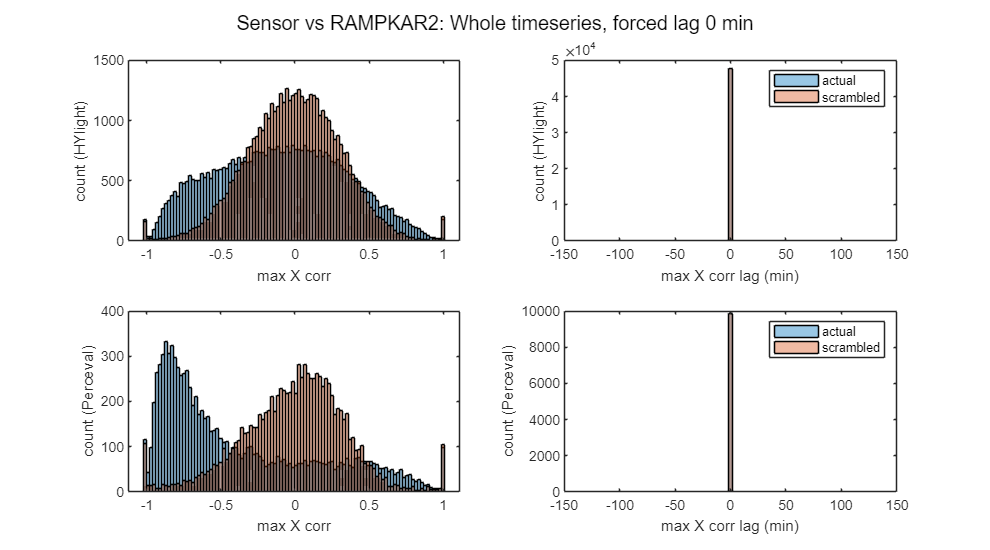

%% Plot histograms again

% HYLIGHT vs RAMPKAR2

binRange = [-150, 150];
edges = linspace(binRange(1), binRange(2), 100); % 100 bins means 51 edges

figure('Renderer', 'painters', 'Position', [10 10 900 500]);
subplot(2,2,1)
histogram(dataHlag.HYLIGHT_RAMPKAR2_maxXcorr,100, Normalization='count');
hold on;
histogram(dataHlag.HYLIGHT_Scrambled_RAMPKAR2_maxXcorr,100, Normalization='count');
alpha(.4);
xlabel('max X corr');
ylabel('count (HYlight)');
subplot(2,2,2)
histogram(dataHlag.HYLIGHT_RAMPKAR2_maxXcorrLagInMin,edges, Normalization='count');
hold on;
histogram(dataHlag.HYLIGHT_Scrambled_RAMPKAR2_maxXcorrLagInMin,edges, Normalization='count');
alpha(.4);
xlim([-150 150]);
xlabel('max X corr lag (min)');
ylabel('count (HYlight)');
legend('actual','scrambled')

% Perceval vs RAMPKAR2

subplot(2,2,3)
histogram(dataPlag.PERCEVAL_RAMPKAR2_maxXcorr,100, Normalization='count');
hold on;
histogram(dataPlag.PERCEVAL_Scrambled_RAMPKAR2_maxXcorr,100, Normalization='count');
alpha(.4);
xlabel('max X corr');
ylabel('count (Perceval)')

subplot(2,2,4)
histogram(dataPlag.PERCEVAL_RAMPKAR2_maxXcorrLagInMin, edges, Normalization='count');
hold on;
histogram(dataPlag.PERCEVAL_Scrambled_RAMPKAR2_maxXcorrLagInMin, edges, Normalization='count');
alpha(.4);
xlim([-150 150]);
xlabel('max X corr lag (min)');
ylabel('count (Perceval)');
legend('actual','scrambled')
sgtitle('Sensor vs RAMPKAR2: Whole timeseries, forced lag 0 min');

### Max xcorr distribution per treatment and pre-treatment

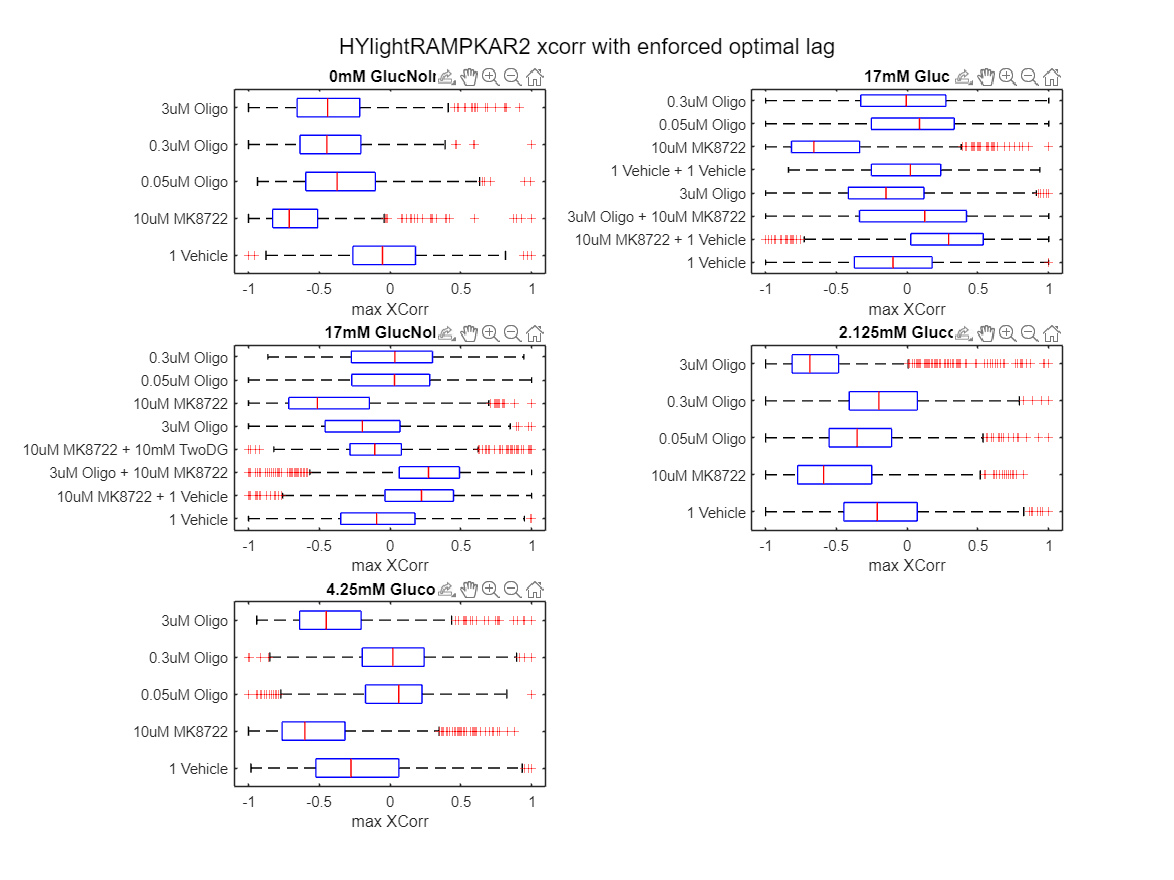

% Get unique pre-treatments
pretreatments = unique(dataHlag.Ptx);

% Prepare figure
figure('Renderer', 'painters', 'Position', [10 10 1200 900]);
numPtx = numel(pretreatments);
rows = ceil(sqrt(numPtx));
cols = ceil(numPtx / rows);

for i = 1:numPtx
    subplot(rows, cols, i);
    
    % Subset data for current Ptx
    subData = dataHlag(strcmp(dataHlag.Ptx, pretreatments{i}), :);
    
    % Boxplot grouped by Tx
    boxplot(subData.HYLIGHT_RAMPKAR2_maxXcorr, subData.Tx, 'Orientation', 'horizontal');
    title(sprintf('%s', pretreatments{i}), 'Interpreter', 'none');
    xlabel('max XCorr');
    set(gca, 'FontSize', 10);
end

sgtitle('HYlightRAMPKAR2 xcorr with enforced optimal lag');

I was suprised by the distribution of the cross-correlations not showing more negatively correlated values for HYlight vs RAMPKAR2. But re-visiting the single cell plots:

- The RAMPAKR2 signal is noisy which may induce positive correlation values between its noise and HYlight's noise

- The majority of cells don't oscillate. I think it would be something like 1/3 (could be checked witht the pulse data frame). So, although by eye it felt like a very obvious pattern, it gets mitigated by the overall cell behavior which is less obviously negatively correlated

- I should check but if there's an trend over time for both sensors it might come up as a positive correlation, which we do see in the HYlight-RAMPAKR2 cells

## Correlate baseline behavior to post-treatment heterogeneous responses (RAMPKAR2 and HYlight)

Extract:

- Pre-oligo HYlight : Mean and time to first peak will allow high, medium, low and oscillatory distinction per cell

- Pre-oligo RAMPKAR2 : Same thing

Divide those into categories and compare/correlate to:

- Post oligo HYlight time to first peak, slope of first peak, number of peaks, amp of peak1 vs peak2 and maybe other parameters

- Post oligo RAMPKAR2 parameters

### Group/Classify baseline behavior (HYlight, RAMPKAR, all [oligo], all [glucose])

#### Load just the RAMPKAR-HYlight pulse analysis data

clear dataHlag dataPlag R2H

for i = 3:5
    deltaR2_HY = convertPulseToDataframe(f2Data{i}, {'HYLIGHT','RAMPKAR2'}, ...
        'pulsepars', {'Mean_Before','Peak_Max','Peak_Mean','Mean_Deriv','Frequency',...
    'Mean_Amp','Peak_Amp','Time2FirstP','Time2SecondP','Time2ThirdP','DurFirstP','DurSecondP','DurThirdP'}, ...
        'aftertx', 1, 'tmaxback', 4, 'tmaxaftertx', 12);
    % Store results
    R2H{i} = deltaR2_HY;

    clear deltaR2_HY 
end
R2H = vertcat(R2H{:});

Filter the data a little more in ordert to get oligo and glucose-only conditions.

R2H = R2H(matches(R2H.Tx, {'1 Vehicle','3uM Oligo','0.3uM Oligo','0.05uM Oligo'}), :);
% clean up labels
R2H.Tx(R2H.Tx == "1 Vehicle 1 Vehicle") = "Vehicle";
R2H.Tx(R2H.Tx == "1 Vehicle") = "Vehicle";

         Value    Count   Percent
       Vehicle     8513     27.65%
  0.05uM Oligo     8536     27.73%
   0.3uM Oligo     6953     22.58%
     3uM Oligo     6784     22.04%


            Value    Count   Percent
    0mM GlucNoIns     3535     11.48%
        17mM Gluc     9182     29.83%
   17mM GlucNoIns     5817     18.89%
  2.125mM Glucose     6074     19.73%
   4.25mM Glucose     6178     20.07%


tabulate(R2H.Tx)
tabulate(R2H.Ptx)

#### Plots for distribution of categories

% Pivot the data for plotting

% Detect variables with sensor data
allVars = R2H.Properties.VariableNames;
isPulseMetric = contains(allVars, {'RAMPKAR2_', 'HYLIGHT_'}, 'IgnoreCase', false);
pulseMetricVars = allVars(isPulseMetric);

% Metadata columns to preserve
metaCols = {'xys', 'Tx', 'Ptx', 'cellidx', 'PtxTx', 'cell', 'exp'};
metaCols = intersect(metaCols, R2H.Properties.VariableNames);

% Initialize storage for long-format tables
longTables = cell(numel(pulseMetricVars), 1);

% Loop through each sensor-specific variable
for i = 1:numel(pulseMetricVars)
    varName = pulseMetricVars{i};
    splitLoc = strfind(varName, '_');
    if isempty(splitLoc), continue; end

    sensor = varName(1:splitLoc(1)-1);
    metric = varName(splitLoc(1)+1:end);

    % Create table with core columns
    temp = table( ...
        repmat(string(sensor), height(R2H), 1), ...
        repmat(string(metric), height(R2H), 1), ...
        R2H.(varName), ...
        'VariableNames', {'Sensor', 'Metric', 'Value'});

    % Add metadata columns
    for m = 1:numel(metaCols)
        temp.(metaCols{m}) = R2H.(metaCols{m});
    end

    longTables{i} = temp;
end

% Concatenate all to produce the final long-format table
R2Hlong = vertcat(longTables{:});  


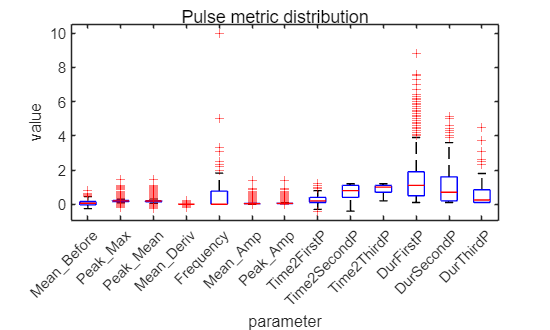

figure('Renderer', 'painters', 'Position', [10 10 500 300]);

boxplot(R2Hlong.Value, R2Hlong.Metric, 'Orientation', 'vertical');
    xlabel('parameter');
    ylabel('value');
    set(gca, 'FontSize', 10);
sgtitle('Pulse metric distribution');
figure('Renderer', 'painters', 'Position', [10 10 1200 400]);

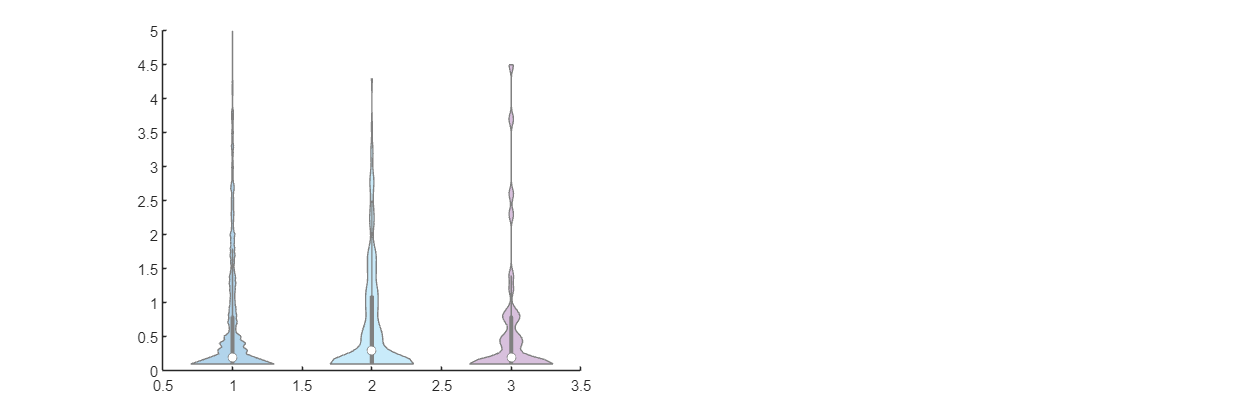

Error using griddedInterpolant
The sample points must be finite.

Error in interp1 (line 170)
    F = griddedInterpolant(X,V(:,1),method);

Error in Violin (line 136)
                jitterstrength = interp1(value, density*width, data);

Error in 


sensors = unique(R2Hlong.Sensor);
nSensors = numel(sensors);

for i = 1:nSensors
    subplot(1, nSensors, i);
    
    % Extract data for this sensor
    thisSensor = sensors{i};
    thisData = R2Hlong(strcmp(R2Hlong.Sensor, thisSensor), :);

    % Make the violin plot
    violinplot(thisData.Value, thisData.Metric);

    title(thisSensor);
    xlabel('Metric');
    ylabel('Hours');
    set(gca, 'XTickLabelRotation', 45);
    set(gca, 'FontSize', 10);
end


sgtitle('Pulse Metric Distribution by Sensor');


## Explore MK8722 effect on HYlight pulses

% %% Violin plots of correlation at optimal lag
% 
% dataHsub = dataHlag(matches(dataHlag.Ptx, {'17mM Gluc'}) & matches(dataHlag.Tx, ...
%         {'1 Vehicle','3uM Oligo','3uM Oligo + 10uM MK8722'}), :);
% dataPsub = dataPlag(matches(dataPlag.Ptx, {'17mM Gluc'}) & matches(dataPlag.Tx, ...
%         {'1 Vehicle','3uM Oligo','3uM Oligo + 10uM MK8722'}), :);
% 
% % clean up legend
% dataHsub.Tx(dataHsub.Tx == "1 Vehicle 1 Vehicle") = "Vehicle";
% dataHsub.Tx(dataHsub.Tx == "1 Vehicle") = "Vehicle";
% dataPsub.Tx(dataPsub.Tx == "1 Vehicle") = "Vehicle";
% %order
% dataHsub.Tx = categorical(dataHsub.Tx,{'Vehicle','3uM Oligo','3uM Oligo + 10uM MK8722'});
% dataPsub.Tx = categorical(dataPsub.Tx,{'Vehicle','3uM Oligo','3uM Oligo + 10uM MK8722'});
% 

% tabulate(dataHsub.tx);
% tabulate(dataPsub.Tx);